# A Comparation between 2 Leak Area Calculation Methods

## 1 前言

目前有两种供水管道地震破坏后泄漏面积计算方法，为了比较两种泄漏面积计算方法对管网水力模拟的影响，对其进行比较研究。

## 2 理论

如 generate_damage_random 类中描述的两个确定泄漏面积的方法

### 2.1 加权平局方法

weightedMeanLeakArea 方法步骤：

- 计算每个管道破坏的概率Pf

- 建立各个管道状态判断矩阵 judge_interval = [0,0.2*Pf,Pf,1]

- 将随机数rand_P与judge_interval进行比较，得到判断矩阵mid_a；

- mid_b=sum(mid_a)

- 若mid_b=1，则表明随机数rand_P大于0，小于0.2*Pf，管道为断开破坏；若mid_b = 2，则表明随机数rand_P大于0.2*Pf，小于Pf，管道为泄漏破坏；若mid_b=3，则表明随机数rand_P大于Pf，小于1，管道为正常。

- 对于断开管道、泄漏管道、正常管道采用不同的方法，本报告关注泄漏管道，泄漏面积计算。

- 对于泄漏管道，泄漏面积与泄漏类型有关，而不同管道的泄漏类型的概率与管道材料有关。因此采用***加权平均***的方法计算泄漏面积：

$Area_{leak} = \sum_{i =1}^{N}P(i)Area(i)$     (1)

式中，$Area_{leak}$为管道泄漏面积；$P(i)$为第$i$个泄漏类型的发生概率；$Area(i)$为第$i$个泄漏类型的泄漏面积。

### 2.2 确定泄漏类型方法

如 LeakAreaByType方法所示：

- 计算管道的破坏概率Pf

- 确定管道的材料

- 根据管道材料确定管道状态判断矩阵judge_interval =[0, P_leak*p1*Pf, P_leak*p2*Pf, P_leak*p3*Pf, P_leak*p4*Pf, P_leak*p5*Pf, Pf, 1] 

- 令mid_a = rand_P>judge_interval

- 令mid_b = sum(mid_a);

- 若mid_b = 1，则为泄漏类型1；若mid_b = 2，则为泄漏类型2；若mid_b=3，则为泄漏类型3；若mid_b = 4，则为泄漏类型4；若mid_b = 5，则为泄漏类型5；若mid_b = 6，则为断开破坏；若mid_b = 7，则管道正常。

- 泄漏面积干燥管道泄漏类型计算。

## 3 案例分析

### 3.1 案例介绍

采用GWSL管网，管网模型如图所示

net = epanet('GWSL_4.inp');

EPANET loaded sucessfuly.
Input File "GWSL_4.inp" loaded sucessfuly.


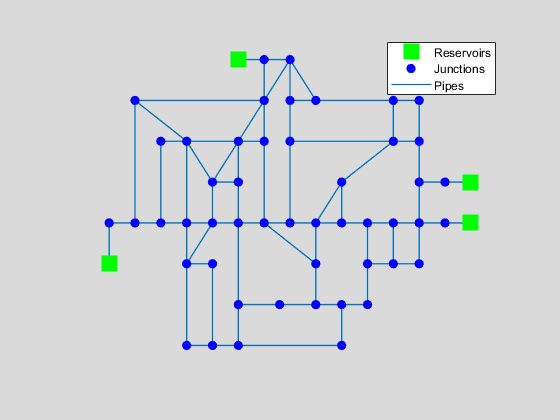

net.plot;

net.delete;

管网参数如下：

No. of Pipes: 78

No. of Junctions 49

No. of Reservoirs 4

No. of tanks 0

Flow Units LPS

Headloss Formula H-W

采用Sobol低偏差序列，对管网进行1000次抽样，水力模拟采用PDD模型。

### 3.2 模拟结果

clear;clc
data_mean = load('sobolpost_data_GWSL_4.mat');
data_each = load('sobol-leakType-post_data_GWSL_4.mat');


#### (1) 供水满足率Q/Q0

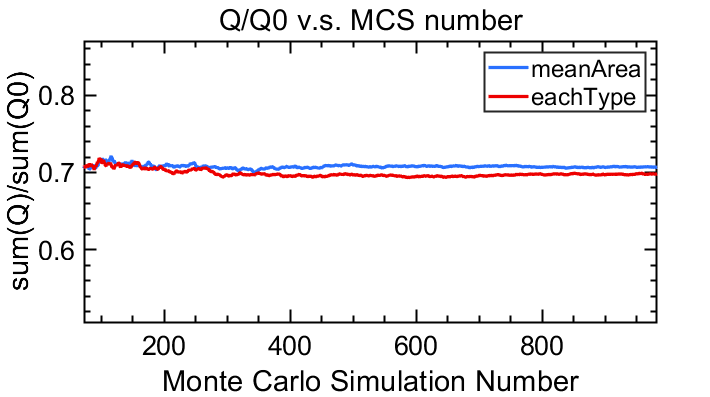

X = 1:data_each.MC_NUM;
Q_mean_m = cumsum(data_mean.SSI_Q)./X;
Q_mean_e = cumsum(data_each.SSI_Q)./X;
plt1 = Plot(X,Q_mean_m,X,Q_mean_e);
f1 = figure(1);
plt1.XLabel = 'Monte Carlo Simulation Number';
plt1.XLabel = 'Monte Carlo Simulation Number';
plt1.YLabel = 'sum(Q)/sum(Q0)';
plt1.Title = 'Q/Q0 v.s. MCS number';
plt1.Legend = {'meanArea','eachType'};
plt1.LegendBox = 'on';

plt1.delete;
epsilon_Q = (Q_mean_m(end)-Q_mean_e(end))/Q_mean_e(end)

epsilon = 0.0121

#### (2) 平均水压H

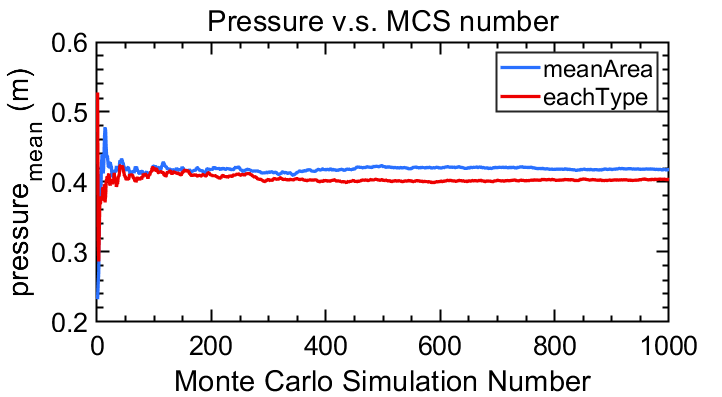

MC_NUM = data_each.MC_NUM;
H_mean_m = cumsum(data_mean.SSI_H)./(1:MC_NUM);
H_mean_e = cumsum(data_each.SSI_H)./(1:MC_NUM);
f2 = figure(2);
p2 = Plot(X,H_mean_m,X,H_mean_e);
p2.XLabel = 'Monte Carlo Simulation Number';
p2.YLabel = 'pressure_m_e_a_n (m)';
p2.Title = 'Pressure v.s. MCS number';
p2.Legend = {'meanArea','eachType'};
p2.LegendBox = 'on';

p2.delete;
f2.delete;
epsilon_H = (H_mean_m(end)-H_mean_e(end))/H_mean_e(end)

epsilon_H = 0.0352

#### (3) 流量SSI均值的变异系数

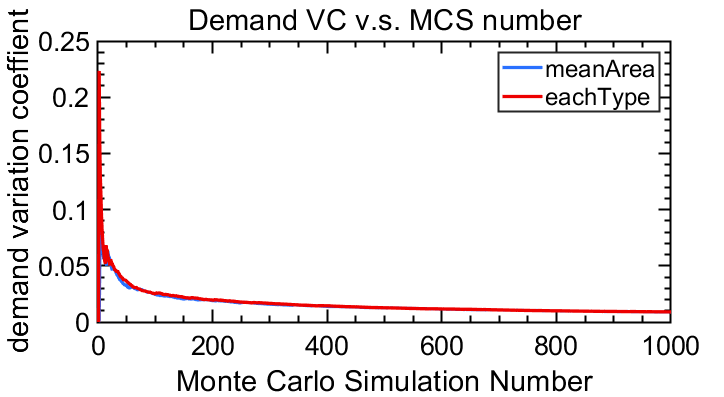

Q_sd_m = sqrt(cumsum((data_mean.SSI_Q-Q_mean_m).^2)./(1:MC_NUM));
Q_vc_m = Q_sd_m./Q_mean_m;
Q_sd_e = sqrt(cumsum((data_each.SSI_Q-Q_mean_e).^2)./(1:MC_NUM));
Q_vc_e = Q_sd_e./Q_mean_e;
Q_mean_vc_m = Q_vc_m./(1:MC_NUM).^0.5;%均值的变异系数(HOU 博士论文第3章)
Q_mean_vc_e = Q_vc_e./(1:MC_NUM).^0.5;
f3 = figure(3);
p3 = Plot(X,Q_mean_vc_m,X,Q_mean_vc_e);
p3.XLabel = 'Monte Carlo Simulation Number';
p3.YLabel = 'demand variation coeffient';
p3.Title = 'Demand VC v.s. MCS number';
p3.Legend = {'meanArea','eachType'};
p3.LegendBox = 'on';
p3.LegendLoc = 'northeast';

f3.delete;
epsilon_vc = (Q_mean_vc_m(end)-Q_mean_vc_e(end))/Q_mean_vc_e(end)

epsilon_vc = -0.0119

#### （4）节点平均水压H的变异系数

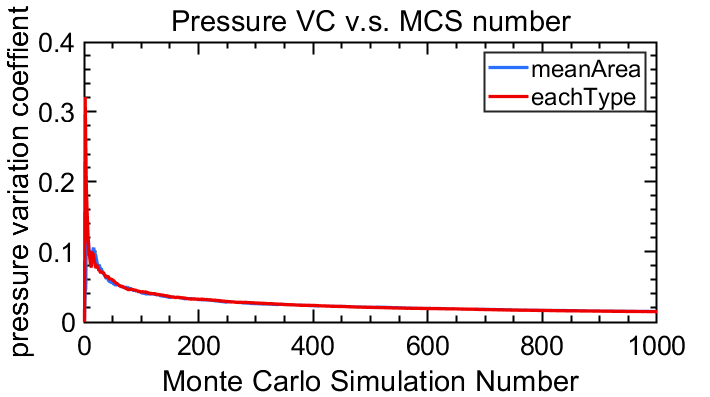

H_sd_m = sqrt(cumsum((data_mean.SSI_H-H_mean_m).^2)./(1:MC_NUM));
H_vc_m = H_sd_m./H_mean_m;
H_sd_e = sqrt(cumsum((data_each.SSI_H-H_mean_e).^2)./(1:MC_NUM));
H_vc_e = H_sd_e./H_mean_e;
H_mean_vc_m = H_vc_m./(1:MC_NUM).^0.5;%均值的变异系数(HOU 博士论文第3章)
H_mean_vc_e = H_vc_e./(1:MC_NUM).^0.5;
f4 = figure(4);
p4 = Plot(X,H_mean_vc_m,X,H_mean_vc_e);
p4.XLabel = 'Monte Carlo Simulation Number';
p4.YLabel = 'pressure variation coeffient';
p4.Title = 'Pressure VC v.s. MCS number';
p4.Legend = {'meanArea','eachType'};
p4.LegendBox = 'on';
p4.LegendLoc = 'northeast';

close(f4)
f4.delete;
epsilon_vc_H = (H_mean_vc_m(end)-H_mean_vc_e(end))/H_mean_vc_e(end)

epsilon_vc_H = 0.0125

### 3.3 统计特征比较

#### (1) 供水满足率

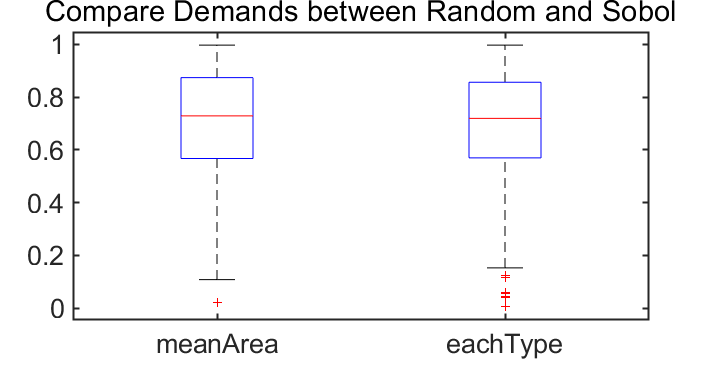

f5 = figure(5);
f5.Units = 'inches';
f5.Position = [7 4.1250 7.3125 3.8094];
bpt1 = boxplot([data_mean.SSI_Q',data_each.SSI_Q'],'Labels',{'meanArea','eachType'},"Widths",0.25);
f5.CurrentAxes.Box = 'on';
f5.CurrentAxes.LineWidth = 1.5;
f5.CurrentAxes.Title.String = 'Compare Demands between Random and Sobol';
f5.CurrentAxes.FontSize = 20;
f5.CurrentAxes.FontName = 'Arial';
% f5.CurrentAxes.Units = 'inches';
pos5 = f5.CurrentAxes.Position;
height = 3;width = 6;
f5.CurrentAxes.Position = [pos5(1),pos5(2),width,height];

close(f5);

#### (2) 平均节点压力H

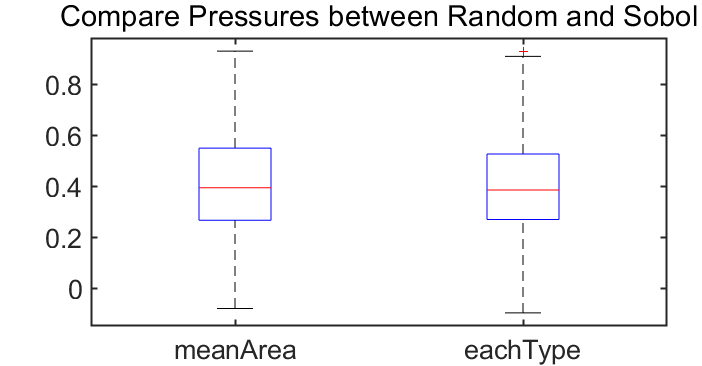

f6 = figure(6);
f = f6;
bpt2 = boxplot([data_mean.SSI_H',data_each.SSI_H'],'Labels',{'meanArea','eachType'},"Widths",0.25);
f.Units = 'inches';
f.Position = [7 4.1250 7.3125 3.8094];
f.CurrentAxes.Box = 'on';
f.CurrentAxes.LineWidth = 1.5;
f.CurrentAxes.Title.String = 'Compare Pressures between Random and Sobol';
f.CurrentAxes.FontSize = 20;
f.CurrentAxes.FontName = 'Arial';
f.CurrentAxes.Units = 'inches';
pos7 = f.CurrentAxes.Position;
height = 3;width = 6;
f.CurrentAxes.Position = [pos7(1),pos7(2),width,height];

#### (3) 供水满足率SSI频数分布

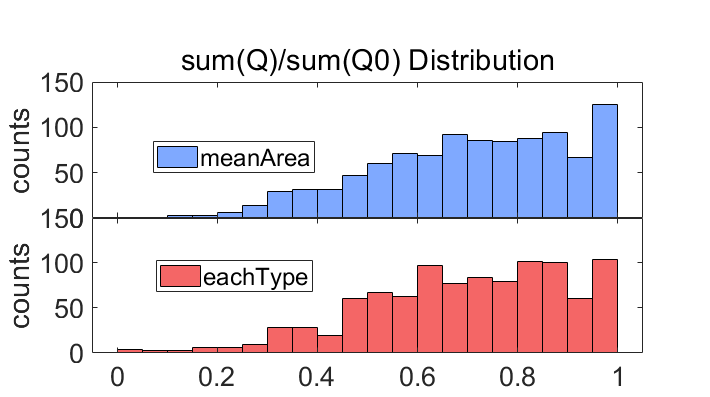

f7 = figure(7);
f = f7;
axe71 = subplot(2,1,1);
ph1 = histogram(data_mean.SSI_Q);
ph1.BinLimits = [0,1];
ph1.NumBins = 20;
ph1.FaceColor = [0.16,0.44,1.00];
axe71.Title.String = 'sum(Q)/sum(Q0) Distribution';
axe71.FontName = 'Arial';
axe71.FontSize = 20;
% axe1.XLabel.String = 'sum(Q)/sum(Q0)';
axe71.YLabel.String = 'counts';
% axe1.Title.String = 'random';
% axe1.Title.Position =  [0.1,90,0]
axe71.XTickLabel = '';
len1 = legend('meanArea');
len1.Position = [0.25,0.58,0.16,0.05];
axe72 = subplot(2,1,2);
ph2 = histogram(data_each.SSI_Q);
ph2.BinLimits = [0,1];
ph2.NumBins = 20;
ph2.FaceColor = [0.93,0,0];
axe72.FontName = 'Arial';
axe72.FontSize = 20;
axe72.XLabel.String= 'sum(Q)/sum(Q0)';
axe72.YLabel.String = 'counts';
% axe2.Title.String = 'sobol';
% axe2.Title.Position =  [0.1,90,0]
len2 = legend('eachType');
len2.Position = [0.25,0.28,0.16,0.05];
pos7 = axe72.Position;
axe72.YLim = [0,150];
axe71.Position = [pos7(1),pos7(2)+pos7(4),pos7(3),pos7(4)];
axe72.Position = pos7;
axe71.YAxis.Limits = axe72.YLim;

close(f);

#### (4) 平均节点压力H的频数

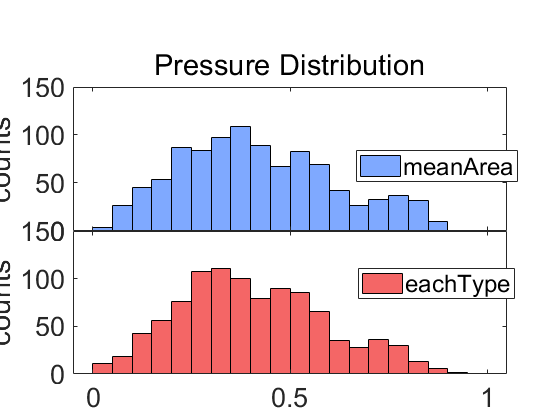

f8 = figure(8);
f = f8;
axe81 = subplot(2,1,1);
ph1 = histogram(data_mean.SSI_H);
ph1.BinLimits = [0,1];
ph1.NumBins = 20;
ph1.FaceColor = [0.16,0.44,1.00];
axe81.Title.String = 'Pressure Distribution';
axe81.FontName = 'Arial';
axe81.FontSize = 20;
axe81.YLabel.String = 'counts';
axe81.XTickLabel = '';
len1 = legend('meanArea');
len1.Position = [0.70,0.58,0.16,0.05];
axe82 = subplot(2,1,2);
ph2 = histogram(data_each.SSI_H);
ph2.BinLimits = [0,1];
ph2.NumBins = 20;
ph2.FaceColor = [0.93,0,0];
axe82.FontName = 'Arial';
axe82.FontSize = 20;
axe82.XLabel.String= 'Pressure (m)';
axe82.YLabel.String = 'counts';
len2 = legend('eachType');
len2.Position = [0.70,0.30,0.16,0.05];
pos8 = axe82.Position;
axe82.YLim = [0 150];
axe81.Position = [pos8(1),pos8(2)+pos8(4),pos8(3),pos8(4)];
axe82.Position = pos8;
axe81.YLim = axe82.YLim;

## 4 结论

两者对结果有影响，但是影响很小。